## Problem Set 1

**October 1, 2026**

### **I. Deterministic Dynamic Programming**

#### **1. a) Dynamic optimization problem**

$v(K_0) = \max_{\{c_t | c_t \in C(K_t)\}_{t=0}^{\infty}} \sum_{t=0}^{\infty} \beta ^t \ln{c_t}$  where $C(K_t)$ is the set of feasible consumption levels given $K_t$ ,

s.t.    $K_{t+1} - K_t = aK_t - \frac{bK_t^2}{2} - c_t$

         $c_t, K_t \geq 0$  $\forall t = 0, 1, 2, ...$ , and

          $K_0$ given,

where $\beta = \frac{1}{1+\rho}$  henceforth.

#### b) Bellman equation


$$v(K_t) = \max_{c_t \in C(K_t)} \ln{c_t} + \beta v(K_{t+1})$$


s.t.    $K_{t+1} - K_t = aK_t - \frac{bK_t^2}{2} - c_t$

         $c_t, K_{t+1} \geq 0$ .

#### c) Interpretation

The value function is $v(K_t)$ which represents the present discounted value from now on of the stream of per-period payoffs when consumption is chosen optimally, given the current state of farm capital $K_t$.

The continuation value is $v(K_{t+1})$ which represents the value of all future payoffs starting from the next period when consumption is chosen optimally given next period's capital stock, which involves a tradeoff with today's choice of consumption.

#### d) Redefine control variable


$$v(K_t) = \max_{K_{t+1}} \ln {(aK_t - \frac{bK_t^2}{2} - K_{t+1} + K_t})+ \beta v(K_{t+1})$$


s.t. $0 \leq K_{t+1} < aK_t - \frac{bK_t^2}{2} + K_t$ .

#### e) Solve for value, policy function

In the following code block, I solve for the value function and policy function as functions of capital stock K. In lines 7-10, I set parameter values as given in the problem. In lines 13-17, I set up the discretized K arrays. In lines 20-22,I define `f_k` as production plus existing capital, which is the total resources available. Subtracting K′ gives consumption, and taking the log gives the payoff matrix. I then initialize values for the loop in lines 25-27. The while loop in lines 30 to 42 calculates for each K, K' pair the value function, finds the arg max, and continues looping until the value function converges as defined by our "diff" condition. The arg max (K' that maximizes value for each K) is identified as "kprime_pol", the policy function. 

% Setup
clearvars;
close all;
clc;

% Define variables and parameters
rho = 0.05;
beta = 1 / (1 + rho);
a = 48.05;
b = 3;

% Create k grids
num_k = 30;
num_kprime = 30;

k = (1:num_k)';
kprime = 1:num_kprime;

% Describe laws of problem
f_k = a*k - b*k.^2 / 2 + k;
c = f_k - kprime; % consumption for every pair
pii = log(c); % payoffs

% Initialize for loop
v = zeros(num_k, 1);
ep = 1e-6;
diff = 1;

% Solve
while diff > ep
    % Reset v to be the previous version
    v_old = v;

    % value of v
    vv = pii + beta * v';

    % For each k, choose kprime to maximize vv
    [v, kprime_pol] = max(vv, [], 2);

    % Calculate diff
    diff = max(abs(v - v_old));
end

% Print results in table
results1 = table(k, v, kprime_pol, 'VariableNames', {'State', 'Value', 'Policy'})

results1 = 30×3 table
    State    Value     Policy
    _____    ______    ______

      1      122.55      13  
      2      123.39      15  
      3      123.82      15  
      4      124.11      15  
      5      124.31      16  
      6      124.47      16  
      7      124.59      16  
      8      124.69      16  
      9      124.77      16  
     10      124.84      16  
     11      124.89      16  
     12      124.93      16  
     13      124.96      16  
     14      124.99      16  
     15         125      16  
     16      125.01      16  

	Get insights using Copilot


#### f) Plot optimal trajectories

Here I solve for the optimal trajectories of capital K(t) and consumption C(t) starting from K₀ = 5. In lines 47-51, I set the number of periods T and initialize the capital path with K₀ = 5. In lines 54-56, I use the policy function to fill in the rest of the capital path: for each period, next period's capital is the policy function evaluated at the current capital. In line 59, I compute consumption in each period from the law of motion, as production plus current capital minus next period's capital. In lines 65-72, I plot both paths against time.

% Pick number of periods
T = 20;

% Store capital in vector
k_path = zeros(T + 1, 1);
k_path(1) = 5; % start at period 5

% Simulate the optimal capital path
for t = 1:T
    k_path(t + 1) = kprime_pol(k_path(t));
end

% Consumption from law of motion
c_path = f_k(k_path(1:T)) - k_path(2:T + 1);

% Plot optimal paths
t_k = 0:T;
t_c = 0:T-1;

figure
plot(t_k, k_path)
hold on
plot(t_c, c_path)
legend('Capital K', 'Consumption C')
xlabel('Time t')
title('Optimal Paths')
ylabel('Capital and consumption')

#### g) Interpret results

The value function v(K) rises with capital up to K = 16 and then falls slightly. The policy function shows that for most starting values of K, the optimal next-period capital is K′ = 16, so 16 is the steady state. Starting from K₀ = 5, capital rises to 16 in only one period and stays there. This one-period jump is partially due to the coarse grid for K (integers 1-30 only). Consumption starts near 190 units and rises to about 385 which is the steady-state output, F(16). We can see that the farming family gives up some consumption early to build capital, which raises consumption in every later period.

#### 2. a) Bellman equation, finite horizon problem

$v_t(K_t) = \max_{K_{t+1}} \ln {(aK_t - \frac{bK_t^2}{2} - K_{t+1} + K_t})+ \beta v_{t+1}(K_{t+1})$ for $t= 0, 1,2,3$, and


$$v_T(K_T) = \ln (aK_T - \frac{bK_T^2}{2} + K_T)$$


s.t. $0 \leq K_{t+1} < aK_t - \frac{bK_t^2}{2} + K_t$ $\forall t = 0, 1, 2, 3$, and

$0 < aK_T - \frac{bK_T^2}{2} + K_T$ , i.e., $c_T > 0$ .

#### b) Interpretation

The value function is $v_t(K_t)$ which represents the present discounted value from now through the last period of the stream of per-period payoffs when next period's capital is chosen optimally, given the current state of farm capital $K_t$.

The continuation value is $v_t(K_{t+1})$ which represents the value of all future payoffs starting from the next period through the final period, when future capital choices are made optimally given next period's capital stock, which involves a tradeoff with today's choice of consumption. Note that there is no continuation value in the Bellman for $t = T =4$, as there is no "future" after the last period.

#### c) Solve

In the following code block, I solve for the value function and policy function as functions of capital stock K and time t, for the finite horizon problem with T = 4. In lines 78-89, I set parameter values and the discretized K grid, as before. In lines 92-94, I compute `f_k`, consumption, and the payoff matrix, the same way as in the infinite horizon case. In lines 99-102, I initialize the value function and set the value function in the last period, t = T, as the payoff from consuming all available resources, since there is no continuation value. In lines 105-114, I iterate backwards from t = T−1 to t = 0: in each period, I compute the value of each K, K′ pair as today's payoff plus the discounted value next period, take the arg max across K′ for each K, and store the results in the corresponding column of `v_t` and `kprime_t`. The result is a full time path of value and policy functions, one column for each period from t = 0 to t = T.

% Setup
clearvars;
close all;
clc;

% Define variables and parameters
rho = 0.05;
beta = 1 / (1 + rho);
a = 48.05;
b = 3;

% Create k grids
num_k = 30;
num_kprime = 30;

k = (1:num_k)';
kprime = 1:num_kprime;

% Describe laws of problem
f_k = a*k - b*k.^2 / 2 + k;
c = f_k - kprime; % consumption for every pair
pii = log(c); % payoffs

T = 4;

% Initialize value function
v = zeros(num_k, T + 1);

% Value function at t=T
v_t(:, T+1) = log(a*k - b*k.^2/2 + k);

% Solve using backwards iteration
for t = T-1:-1:0
    % Initialize vv
    vv = pii + beta * v_t(:, t+2)';

    % Choose optimal actions
    [v_now, kprime_now] = max(vv, [], 2);
    v_t(:, t + 1) = v_now;
    kprime_t(:, t+1) = kprime_now;

end

% Print results in table
results2 = table(k, v_t, kprime_t, 'VariableNames', {'State', 'Value', 'Policy'})

results2 = 30×3 table
    State                        Value                                Policy       
    _____    ______________________________________________    ____________________

      1      24.642    19.746    14.606    9.2101    3.8618    13    13    13    13
      2       25.48    20.585    15.444    10.047    4.5229    15    15    15    15
      3      25.911    21.016    15.875    10.478    4.8952    15    15    15    15
      4      26.193    21.297    16.157    10.759    5.1487    15    15    15    15
      5      26.398    21.502    16.362    10.964    5.3363    16    16    16    16
      6      26.555    21.659    16.518    11.121    5.4819    16    16    16    16
      7      26.678    21.783    16.642    11.245    5.5979    16    16    16    16
      8      26.778    21.882    16.742    11.344    5.6917    16    16    16    16
      9      26.858    21.963    16

#### d) Plot optimal trajectories

Here I solve for the optimal trajectories of capital K(t) and consumption C(t) starting from K₀ = 5, over the family's finite horizon until T = 4. In lines 123-126, I use the time-specific policy function to fill in the rest of the capital path: for each period t, next period's capital is the policy function evaluated at the current capital and the current period. I then set capital at t = T+1 to 0 since the family's lifetime ends at T. In line 129, I compute consumption in each period from the law of motion, the same as in the infinite horizon case. In lines 132-142, I plot both paths against time.

% Store capital in vector
k_path = zeros(T + 1, 1);
k_path(1) = 5; % start at period 5

% Simulate the optimal capital path
for t = 0:T-1
    k_path(t + 2) = kprime_t(k_path(t+1), t+1);
end
k_path(T+1) = 0;

% Consumption from law of motion
c_path = f_k(k_path(1:T)) - k_path(2:T + 1);

% Plot optimal paths
t_k = 0:T;
t_c = 0:T-1;

figure
plot(t_k, k_path)
hold on
plot(t_c, c_path)
legend('Capital K', 'Consumption C')
xlabel('Time t')
title('Optimal Paths')
ylabel('Capital and consumption')

#### e) Interpret results

Starting from K₀ = 5, capital rises to 16 by t = 1, similar to the infinite horizon case, and stays there through t = 3. In the last period, capital drops to 0, since any capital left at the end of the family's lifetime produces no further value. Consumption starts near 192 units, rises to about 385 once capital reaches its interior peak of 16, and then jumps to about 401 in the last period, as the family consumes both its usual output and the capital it would otherwise leave behind. This is the key difference from the infinite horizon case: because the family knows exactly when its lifetime ends, it draws down its capital stock entirely rather than maintaining it forever. Thus there is a consumption spike at t = 3, differently than in the infinite horizon path.

v

### **I. Stochastic Dynamic Programming**

#### **1. a)** Bellman equation


$$v(K_t) = \max_{c_t \in C(K_t)} \ln{c_t} + \beta \, \mathbb{E} ( v(K_{t+1}) | K_t, c_t)$$


s.t.    $K_{t+1} - K_t = aK_t - \frac{bK_t^2}{2} - c_t + \varepsilon_t$

         $c_t, K_{t+1} \geq 0$ .

#### b) Interpretation

The value function is $v(K_t)$ which represents the present discounted value from now on of the stream of per-period payoffs when consumption is chosen optimally, given the current state of farm capital $K_t$.

The continuation value is $\mathbb{E}(v(K_{t+1}))$ which represents the expected value of all future payoffs starting from the next period when consumption is chosen optimally given next period's capital stock, which is not known with certainty due to the random shock, and which involves a tradeoff with today's choice of consumption.

#### c) Redefine control variable

Let $I \equiv F(K) - C + K$, so now $K_{t+1} = I_t + \varepsilon_t$ . Then


$$v(K_t) = \max_{I} \ln {(aK_t - \frac{bK_t^2}{2} - I + K_t})+ \beta \, \mathbb{E} v(I+\varepsilon_t)$$


s.t. $2 \leq I \leq 29$ and 

$aK_t - \frac{bK_t^2}{2} + K_t >I$.

#### d) Solve for value, policy function

In the following code block, I solve for the value function and policy function as functions of capital stock K, for the stochastic infinite horizon problem with control variable I. In lines 149-156, I set parameter values as given in the problem, including the shock distribution. In lines 159-163, I set up the discretized K and I grids, where I ranges from 2 to 29 to ensure K′ = I + ε stays on the grid regardless of the realized shock (as in c)). In line 166, I define f_k as production plus existing capital; subtracting I gives consumption, and taking the log gives the payoff matrix. I then initialize values for the loop in lines 171-173. The while loop in lines 176-189 calculates, for each I, the expected continuation value by averaging the value function over the three possible realizations of K′ = I + ε, weighted by their probabilities. I then add this expected continuation value to the payoff matrix, find the arg max across I for each K, and continue looping until the value function converges as defined by our "diff" condition. The arg max (I that maximizes value for each K) is identified as "I_pol", the policy function, since it determines the distribution of next period's capital. 

% Setup
clearvars;
close all;
clc;

% Define variables and parameters
rho = 0.05;
beta = 1 / (1 + rho);
a = 48.05;
b = 2;

% Define shock distribution
eps_vals = [-1, 0, 1];
eps_probs = [0.25, 0.45, 0.30];

% Create I grid
Igrid = 2:29;

% Create k
num_k = 30;
k = (1:num_k)';

% Describe laws of problem
f_k = a*k - b*k.^2 / 2 + k;
c = f_k - Igrid; % consumption for every pair
pii = log(c); % payoffs

% Initialize for loop
v = zeros(num_k, 1);
ep = 1e-6;
diff = 1;

% Solve
while diff > ep
    % Reset v to be the previous version
    v_old = v;

    % value of v
    Ev = 0.25*v(Igrid-1) + 0.45*v(Igrid) + 0.30*v(Igrid + 1);
    vv = pii + beta * Ev';

    % For each k, choose kprime to maximize vv
    [v, I_pol] = max(vv, [], 2);

    % Calculate diff
    diff = max(abs(v - v_old));
end

% Print results in table
results3 = table(k, v, I_pol, 'VariableNames', {'State', 'Value', 'Policy'})

results1 = 30×3 table
    State    Value     Policy
    _____    ______    ______

      1      130.49      15  
      2      131.42      19  
      3      131.89      21  
      4       132.2      22  
      5      132.43      22  
      6       132.6      22  
      7      132.75      22  
      8      132.86      22  
      9      132.96      23  
     10      133.05      23  
     11      133.12      23  
     12      133.19      23  
     13      133.24      23  
     14      133.29      23  
     15      133.33      23  
     16      133.37      23  

	Get insights using Copilot


#### e) Plot optimal trajectories

TO DO

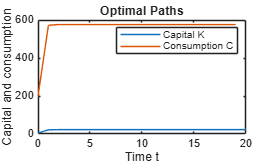

% Pick number of periods
T = 100000;

% Store capital in vector
k_path = zeros(T + 1, 1);
k_path(1) = 5; % start at period 5

% Simulate the optimal capital path
for t = 1:T
    k_path(t + 1) = kprime_pol(k_path(t));
end

% Consumption from law of motion
c_path = f_k(k_path(1:T)) - k_path(2:T + 1);

% Plot optimal paths
t_k = 0:T;
t_c = 0:T-1;

figure
plot(t_k, k_path)
hold on
plot(t_c, c_path)
legend('Capital K', 'Consumption C')
xlabel('Time t')
title('Optimal Paths')
ylabel('Capital and consumption')

#### f) Interpret results

TO DO